# CCLE GCP Ratios

**Author:** Scott Campit

## Summary

This script computes the correlation between the raw CCLE metabolomics data and ratios of histone markers.

clear all;

% First we need to clean up the metabolomics dataset
metabolomics = readtable('CCLE_metabolomics_processed.xlsx', 'sheet', 'all');

metabolomics_ccl = extractBefore(string(table2cell(metabolomics(:, 'CCLE_ID'))), '_');
metabolomics(:, 'CCLE_ID') = cellstr(metabolomics_ccl);
% Next, we need to map between datasets
gcp = readtable('GCP_proteomics_remapped.xlsx', 'sheet', 'all');

[~, ia, ib] = intersect(string(table2cell(metabolomics(:, 'CCLE_ID'))), ...
                        string(table2cell(gcp(:, 'CellLine'))));
                    
% Finally, let's get tables with matching indicies
metabolomics = metabolomics(ia, :);
gcp = gcp(ib, :);

## Methylation and acetylation subsets

% I will also load data subsets and map them
methylation_metabolomics = readtable('CCLE_metabolomics_processed.xlsx', 'sheet', 'methylation');

methylation_metabolomics(:, 'CCLE_ID') = cellstr(metabolomics_ccl);
methylation_gcp = readtable('GCP_proteomics_remapped.xlsx', 'sheet', 'methylation');

methylation_metabolomics = methylation_metabolomics(ia, :);
methylation_gcp = methylation_gcp(ib, :);
data = rescale(table2array(methylation_gcp(:, 2:end)));
methylation_gcp(:, 2:end) = array2table(data);

acetylation_metabolomics = readtable('CCLE_metabolomics_processed.xlsx', 'sheet', 'acetylation');

acetylation_metabolomics(:, 'CCLE_ID') = cellstr(metabolomics_ccl);
acetylation_gcp = readtable('GCP_proteomics_remapped.xlsx', 'sheet', 'acetylation');

acetylation_metabolomics = acetylation_metabolomics(ia, :);
acetylation_gcp = acetylation_gcp(ib, :);
data = rescale(table2array(acetylation_gcp(:, 2:end)));
acetylation_gcp(:, 2:end) = array2table(data);

## Computing meaningful ratios of histone markers

In general, H3K4, H3K36, and H3K79 methylations are generally considered to indicate active transcription, while H3K9 and H3K27 indicate repression. Thus, meaningful ratios of histone markers include:

- H3K4me3 and H3K27me3: [https://ashpublications.org/blood/article/114/22/1046/110138/Modulation-of-Histone-H3K4-and-H3K27-Methylation](https://ashpublications.org/blood/article/114/22/1046/110138/Modulation-of-Histone-H3K4-and-H3K27-Methylation)

- H3K4me3 and H3K9me3

- H3K36me3 and H3K9me3

- H3K36me3 and H3K27me3

- H3K79me2 and H3K9me3

- H3K79me2 and H3K27me2

- All Ac/ All Me

### All acetylation over all methylation

This modules computes acetylation / methylation ratios across all cancer cell lines.

cellLines = table2array(methylation_gcp(:, 'CellLine'))

cellLines = 860×1 cell array
    {'22RV1'   }
    {'2313287' }
    {'42MGBA'  }
    {'59M'     }
    {'697'     }
    {'769P'    }
    {'786O'    }
    {'8305C'   }
    {'8505C'   }
    {'8MGBA'   }
    {'A101D'   }
    {'A172'    }
    {'A204'    }
    {'A2058'   }
    {'A253'    }
    {'A2780'   }
    {'A375'    }
    {'A3KAW'   }
    {'A498'    }
    {'A4FUK'   }
    {'A549'    }
    {'A673'    }
    {'A704'    }
    {'ABC1'    }
    {'ACCMESO1'}
    {'ACHN'    }
    {'AGS'     }
    {'ALLSIL'  }
    {'AM38'    }
    {'AML193'  }


### Compute ratios between acetylation and methylation marks

h3k4_ac_me = table2array(acetylation_gcp(:, 'H3K4ac1')) ./ table2array(methylation_gcp(:, ["H3K4me1", "H3K4me2"]))

h3k4_ac_me =     0.7544    0.7513
    1.1105    1.1006
    1.0894    1.0214
    0.9470    0.9669
    0.9410    0.9392
    1.0426    1.0751
    1.0691    1.0253
    1.1623    1.2114
    1.0417    0.9837
    1.0125    0.9471


h3k9_ac_me = table2array(acetylation_gcp(:, 'H3K9ac1')) ./ table2array(methylation_gcp(:, ["H3K9me1", "H3K9me2", "H3K9me3"]))

h3k9_ac_me =     0.9929    1.0297    1.2152
    1.0714    1.1373    1.1702
    1.0653    1.1833    1.4092
    1.0379    1.0618    1.0975
    0.9588    0.9366    0.9422
    1.0201    1.0627    1.0887
    0.9990    1.0339    1.1360
    1.0633    1.0607    1.1591
    1.1821    1.1327    1.1330
    1.1736    1.2204    1.0691


h3k27_ac_me = table2array(acetylation_gcp(:, 'H3K27ac1')) ./ table2array(methylation_gcp(:, ["H3K27me1", "H3K27me2", "H3K27me3"]))

h3k27_ac_me =     1.2157    1.1948    1.2156
    1.1135    1.1483    1.1163
    1.1653    1.0604    1.0513
    1.0191    1.0458    1.0297
    1.0511    1.3050    1.9103
    1.1422    1.1458    1.2874
    1.0961    1.0433    1.1001
    0.8601    0.9320    1.0436
    0.9708    1.1273    1.2539
    1.1319    1.2730    1.2703


ACME = [h3k4_ac_me, h3k9_ac_me, h3k27_ac_me]

ACME =     0.7544    0.7513    0.9929    1.0297    1.2152    1.2157    1.1948    1.2156
    1.1105    1.1006    1.0714    1.1373    1.1702    1.1135    1.1483    1.1163
    1.0894    1.0214    1.0653    1.1833    1.4092    1.1653    1.0604    1.0513
    0.9470    0.9669    1.0379    1.0618    1.0975    1.0191    1.0458    1.0297
    0.9410    0.9392    0.9588    0.9366    0.9422    1.0511    1.3050    1.9103
    1.0426    1.0751    1.0201    1.0627    1.0887    1.1422    1.1458    1.2874
    1.0691    1.0253    0.9990    1.0339    1.1360    1.0961    1.0433    1.1001
    1.1623    1.2114    1.0633    1.0607    1.1591    0.8601    0.9320    1.0436
    1.0417    0.9837    1.1821    1.1327    1.1330    0.9708    1.1273    1.2539
    1.0125    0.9471    1.1736    1.2204    1.0691    1.1319    1.2730    1.2703


ACME(isnan(ACME)) = 0;
ACME(ACME==inf) = max(ACME(isfinite(ACME)));

### Compute correlations between acetylation:methylation ratios and the raw metabolomics data

gcp_ratios = ["H3K4 ac/me1", "H3K4 ac/me2", ...
              "H3K9 ac/me1", "H3K9 ac/me2", "H3K9 ac/me3", ...
              "H3K27 ac/me1", "H3K27 ac/me2", "H3K27 ac/me3"];

#### Acetylation metabolomics and GCP ratios

First we'll get the metabolomics data we need

acetylation_metabolomics(:, ["CCLE_ID", "DepMap_ID"]) = [];
ac_metabolites = string(acetylation_metabolomics.Properties.VariableNames);
acetylation_metabolomics = table2array(acetylation_metabolomics);

Next, we'll compute the correlation between the GCP ratios and the acetylation metabolomics

[acme_acetylation_corr, acme_acetylation_pval] = corr(ACME, acetylation_metabolomics)

acme_acetylation_corr =    -0.0116    0.0952   -0.0407    0.0167    0.0280   -0.0713   -0.0643   -0.0702   -0.0896   -0.0543   -0.0530    0.0018   -0.0236    0.0236   -0.0585   -0.0832   -0.1182   -0.1171   -0.1377   -0.0263   -0.1611   -0.0821   -0.0599   -0.0620   -0.0671
    0.0127    0.0407   -0.0090    0.0337    0.0263   -0.0486   -0.0464   -0.0685   -0.0640   -0.0522   -0.0194    0.0156    0.0130   -0.0017   -0.0115   -0.0376   -0.0580   -0.0620   -0.0850   -0.0042   -0.1238   -0.0435   -0.0364   -0.0237   -0.0236
    0.0523    0.0578    0.0068    0.0334    0.0542    0.0728    0.0852    0.1024    0.0305    0.0983   -0.0432    0.0411   -0.0652    0.0488   -0.0389    0.0087   -0.0149   -0.0022    0.0030    0.0048    0.0055    0.0113    0.0312    0.0753    0.0365
    0.0456    0.0582    0.0395    0.0524    0.0901    0.0869    0.1018    0.1057    0.0415    0.0851   -0.0263    0.0632   -0.0591   -0.0074   -0.0786    0.0039    0.0024    0.0164    0.0103   -0.0119   -0.0120    0.0334   

mask = acme_acetylation_corr;
mask(acme_acetylation_pval > 0.05) = NaN;

Finally, we'll plot the data as a heatmap

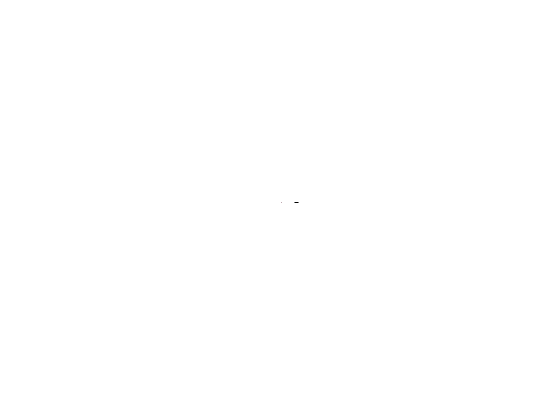

redbluecmap = imresize(redbluecmap, [1000, 3]); redbluecmap = min(max(redbluecmap, 0), 1);
ac_metabolites = strrep(ac_metabolites, '_', ' ');
heatmap(mask', ...
        'colormap', redbluecmap, ...
        'YData', ac_metabolites, ...
        'XData', gcp_ratios, ...
        'FontSize', 45)

#### Methylation metabolomics and GCP ratios

First we'll get the metabolomics data we need

methylation_metabolomics(:, ["CCLE_ID", "DepMap_ID"]) = [];
me_metabolites = string(methylation_metabolomics.Properties.VariableNames);
methylation_metabolomics = table2array(methylation_metabolomics);

Next, we'll compute the correlation between the GCP ratios and the acetylation metabolomics

[acme_methylation_corr, acme_methylation_pval] = corr(ACME, methylation_metabolomics)

acme_methylation_corr =    -0.0883   -0.0713   -0.0643    0.0691    0.0353   -0.0151   -0.0531   -0.0907   -0.0814   -0.0639    0.0231   -0.0526    0.0777    0.0887
   -0.0574   -0.0486   -0.0464    0.0231    0.0472    0.0075   -0.0114   -0.0323   -0.0441   -0.0161   -0.0003   -0.0272    0.0575    0.0762
    0.0949    0.0728    0.0852    0.0700    0.0055   -0.0787    0.0394   -0.0166   -0.0467    0.0938    0.0990   -0.0825   -0.1093    0.0615
    0.1013    0.0869    0.1018    0.0465   -0.0093   -0.0952    0.0191    0.0042   -0.0331    0.0366    0.0734   -0.0380   -0.0949    0.0528
   -0.0380    0.0537    0.0601    0.0541    0.0050   -0.0577   -0.0187   -0.0867   -0.0864    0.0321    0.1584   -0.0669   -0.0870    0.0683
   -0.0968   -0.0246    0.0159    0.0570    0.0020    0.0134   -0.0124   -0.0840   -0.1136    0.0196    0.0936   -0.0316   -0.0501    0.0339
   -0.0393   -0.0208    0.0166    0.0322   -0.0227   -0.0292   -0.0132   -0.0530   -0.0881    0.0225    0.0550   -0.0558   -0.0151

mask = acme_methylation_corr;
mask(acme_methylation_pval > 0.05) = NaN;

Finally, we'll plot the data as a heatmap

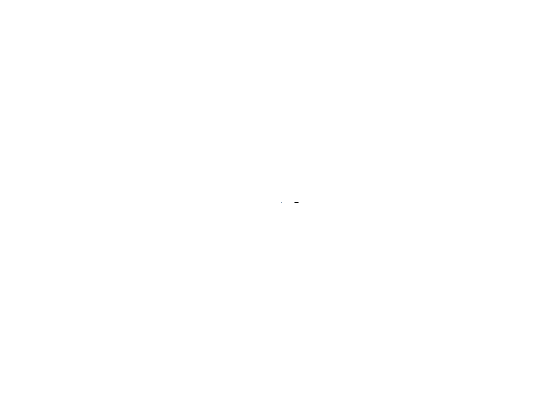

me_metabolites = strrep(me_metabolites, '_', ' ');
heatmap(mask', ...
        'colormap', redbluecmap, ...
        'YData', me_metabolites, ...
        'XData', gcp_ratios, ...
        'FontSize', 45)